# Pb7

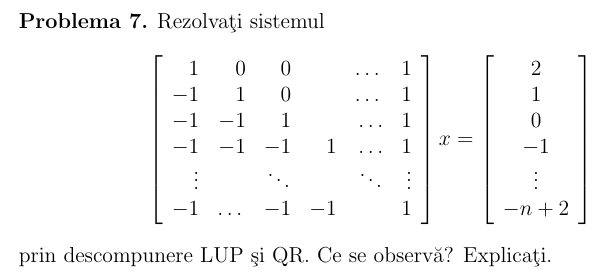

% PB2
function [L, U, p] = lup_decomp(A)
% INPUT:
%   A - matricea coeficientilor (n x n), nesingulara
%
% OUTPUT:
%   L - matrice triunghiulara inferiora cu 1 pe diagonala
%   U - matrice triunghiulara superiora
%   p - vectorul de permutare al liniilor
%
% Algoritm: Descompunere LUP dupa schema din curs (Algoritmul 3)
% PA = LU, unde P este reprezentata prin vectorul p

    m = size(A,1);   % dimensiunea matricei
    p = 1:m;         % initializam vectorul de permutare: p = 1 : m
    U = A;           % initial, U este matricea A
    L = eye(m);      % initial, L este matricea identitate

    for k = 1:m-1
        % -------------------------
        % {Pivotare}
        % Cautam indexul i >= k care maximizeaza |U(i,k)|
        [~, idx] = max(abs(U(k:end, k)));
        i = idx + k - 1;

        % Interschimbam liniile k si i in U
        if i ~= k
            U([k i], :) = U([i k], :);             % A_k <-> A_i
            L([k i], 1:k-1) = L([i k], 1:k-1);     % Interschimbare in L doar pana la coloana k-1
            p([k i]) = p([i k]);                   % pk <-> pi in vectorul de permutare
        end

        % -------------------------
        % {Calculez complementul Schur}
        for lin = k+1:m
            % A_lin,k := A_lin,k / A_k,k   (salvam in L coeficientii de eliminare)
            L(lin, k) = U(lin, k) / U(k, k);

            % A_lin,lin := A_lin,lin − A_lin,k * A_k,lin
            U(lin, :) = U(lin, :) - L(lin, k) * U(k, :);
        end
    end
end

function x = rezolva_lup_sistem(L, U, b, p)
% INPUT:
%   L - matrice triunghiulara inferior (cu 1 pe diagonala)
%   U - matrice triunghiulara superior
%   b - vectorul termenilor liberi (n x 1)
%   p - vectorul de permutare obtinut in descompunere
%
% OUTPUT:
%   x - vectorul solutie al sistemului Ax = b
%
% Metoda: rezolvare sistem cu LUP:
%   1. rezolva Ly = Pb (descendent)
%   2. rezolva Ux = y  (ascendent)

    n = length(b);
    y = zeros(n, 1);
    x = zeros(n, 1);

    % Aplicam permutarea la b
    b_perm = b(p);

    % Substitutie directa (Ly = b_perm)
    for i = 1:n
        y(i) = b_perm(i) - L(i, 1:i-1) * y(1:i-1);
    end

    % Substitutie inversa (Ux = y)
    for i = n:-1:1
        x(i) = (y(i) - U(i, i+1:n) * x(i+1:n)) / U(i, i);
    end
end

## Descompunerea QR

function [Q, R] = qr_descompunere(A)
% INPUT:
%   A - matrice reala (n x m), cu n >= m si coloane liniar independente
%
% OUTPUT:
%   Q - matrice ortogonala (n x m)
%   R - matrice triunghiulara superioara (m x m)
%
% Metoda: Descompunere QR prin Gram-Schmidt modificat
% A = Q * R

    [n, m] = size(A);
    Q = zeros(n, m);
    R = zeros(m, m);

    for j = 1:m
        v = A(:, j);

        % Eliminam componentele deja ortogonalizate
        for i = 1:j-1
            R(i, j) = Q(:, i)' * A(:, j);
            v = v - R(i, j) * Q(:, i);
        end

        % Normalizam vectorul
        R(j, j) = norm(v);
        Q(:, j) = v / R(j, j);
    end
end

function x = backsub(R, y)
% INPUT:
%   R - matrice triunghiulara superioara (n x n)
%   y - vector coloana (n x 1), rezultat din Q^T * b
%
% OUTPUT:
%   x - solutia sistemului R * x = y
%
% Metoda: Substitutie inapoi (Backward substitution)
% Se rezolva sistemul pornind de la ultima ecuatie catre prima

    n = length(y);      % dimensiunea sistemului
    x = zeros(n,1);     % initializare vector solutie

    % Parcurgere de la ultima linie la prima
    for i = n:-1:1
        % x(i) = ( y(i) - suma R(i,j) * x(j) pentru j = i+1..n ) / R(i,i)
        x(i) = (y(i) - R(i,i+1:end) * x(i+1:end)) / R(i,i);
    end
end


clc; clear;

% ----------------------------
% Parametrii problemei
n = 10;
[A, b] = genereaza_sistem_pb7(n);  % Genereaza matricea A si vectorul b

% ----------------------------
% Rezolvare cu LUP
[L, U, p] = lup_decomp(A);
x_lup = rezolva_lup_sistem(L, U, b, p);

% ----------------------------
% Rezolvare cu QR
[Q, R] = qr_descompunere(A);
y = Q' * b;
x_qr = backsub(R, y);  % Substitutie inapoi

% ----------------------------
% Solutie MATLAB (etalon)
x_direct = A \ b;

% ----------------------------
% Afisare solutii cu precizie ridicata
disp('x (LUP):');      disp(vpa(x_lup, 24));


===== SOLUTII OBTINUTE =====


x (LUP):


$$\left(\begin{array}{c} 0.998046875\\ 0.99609375\\ 0.9921875\\ 0.984375\\ 0.96875\\ 0.9375\\ 0.875\\ 0.75\\ 0.5\\ 1.001953125 \end{array}\right)$$

disp('x (QR):');       disp(vpa(x_qr, 24));

x (QR):


$$\left(\begin{array}{c} 0.998046875\\ 0.99609375\\ 0.9921875\\ 0.984375\\ 0.96875\\ 0.9375\\ 0.875\\ 0.75\\ 0.5\\ 1.001953125 \end{array}\right)$$

disp('x (MATLAB):');   disp(vpa(x_direct, 24));

x (MATLAB):


$$\left(\begin{array}{c} 0.998046875\\ 0.99609375\\ 0.9921875\\ 0.984375\\ 0.96875\\ 0.9375\\ 0.875\\ 0.75\\ 0.5\\ 1.001953125 \end{array}\right)$$


% ----------------------------
% Evaluare erori numerice
err_lup = norm(x_lup - x_direct);
err_qr  = norm(x_qr  - x_direct);

fprintf('\n===== ERORI FATA DE MATLAB =====\n');


===== ERORI FATA DE MATLAB =====


fprintf('Eroare LUP: %.3e\n', err_lup);

Eroare LUP: 0.000e+00


fprintf('Eroare QR : %.3e\n', err_qr);

Eroare QR : 2.542e-15



% ----------------------------
% Observatie:
fprintf('\n===== OBSERVATII =====\n');


===== OBSERVATII =====


if err_lup > err_qr
    fprintf('Metoda QR este mai stabila numeric decat LUP pentru acest sistem.\n');
else
    fprintf('Metoda LUP a oferit rezultate similare sau mai bune decat QR in acest caz.\n');
end

Metoda LUP a oferit rezultate similare sau mai bune decat QR in acest caz.
